# **OvertureTireScript**

## **Scope**

- Output tire clearances

- Output tire limits (Loads, Speeds, Temp)

- Verify feasability

## **Input Goodyear Data-Section-2022**

[**https://www.goodyearaviation.com/resources/tiredatabook.html**](https://www.goodyearaviation.com/resources/tiredatabook.html)

close all
clear
clc

As=0;Q=0;

ClassThreePart = readtable('GoodyearDataSection2022.xlsx',Range='A4:Y135');

ClassTypeI = readtable('GoodyearDataSection2022.xlsx',Range='A139:Y140');

ClassTypeIII = readtable('GoodyearDataSection2022.xlsx',Range='A144:Y208');

ClassVII = readtable('GoodyearDataSection2022.xlsx',Range='A212:Y281');

ClassMetric = readtable('GoodyearDataSection2022.xlsx',Range='A285:Y295');

ClassRadial = readtable('GoodyearDataSection2022.xlsx',Range='A299:Y342');

## **Defintions**

**Ply Rating:** The term “Ply Rating” is used to identify a given tire with its maximum recommended load when used in a specific type of service. It is an index of tire strength and does not necessarily represent the number of carcass plies in the tire.  

**TT or TL:** Designates whether the tire is tube-type or tubeless construction  

**Rated Speed:** The maximum speed, normally in miles per hour, to which the tire is qualified.  

**Rated Load:** The maximum load rating in pounds.  

**Rated Inflation:** The inflation pressure required for the tire to support the rated load.  

**Max Braking Load:** The maximum steady braking load which may be applied to a tire.  

**Max Bottoming Load:** Approximate load required to bottom the tire on the rim at rated inflation pressure.  

**Part Number:** The Goodyear part number assigned to the tire if applicable.  

**Inflated Dimensions:** The dimensions of a new tire inflated to rated inflation pressure.  

**Static Loaded Radius:** The distance from the center of the axle to the deflected tread surface under normal load and inflation pressure.  

**Flat Tire Radius:** The distance from the center of the axle to the deflected tread surface when  subjected to bottoming load.  

**Aspect Ratio:** The ratio of tire section height to tire section width.  

**Wheel:** The dimensions of the wheel on which the tire is to be used.  

**LST:** Load, speed, and time curve.  

**SCD:** Specification Control Document.  

**T&RA:** The Tire and Rim Association  

**U:** Universal LST Curve (TSO-C62e)  

**DT:** Deflector Type. (Nosewheel chine)  

**DDT:** Dual Deflector Type.

#### Tire Classification Types

**Three Part Type:** All new sizes being developed are in this classification. 

NOTE: Some sizes have a  letter such as “H” in front of the diameter. This is to identify a tire that is designed for a higher percent deflection.

**Radial:** Radial size nomenclature is the same as Three Part Type except an “R” replaces the  “-“ (dash) before the wheel/rim diameter.

-The rest are outdated classification types

## Background 

#### Main Wheel Tire Notes:

**(1)** Aircraft size generally grows during the life cycle of the airframe from prototype to first production units  and eventually to heavier weight versions to meet operator requirements. Selecting a tire that permits an increased load  capability will help avoid the costly necessity of changing tire size or wheel details required to support heavier aircraft  versions.

**(2)** The main wheel tire requirements should be based upon the most aft center of gravity location and the ground operational  load-speed-time history considered to be the most severe during normal service operations. Consideration should be given  to operations at high density altitudes.

#### Nose Wheel Tire Notes:

**(1) **It is important that selection of a nose wheel tire be reviewed from both a static load requirement  and a dynamic braking condition. 

**(2)** Care should be taken during initial selection to allow for loading growth to avoid possible  future retrofitting. Nose wheel tire selection should be based on the most forward center of gravity load.

#### Operating Tire Temperatures:

Aircraft tires shown in Goodyear handbook are not recommended for use where surface temperatures exceed 225°F (107°C), or  where brake heat results in temperatures that exceed 300°F (149°C) at wheel surfaces adjacent to the tire and tube.  Consult Goodyear for operation outside these limits.

#### Random Note:

Radius of gyration=(Max O.D. + Min O.D)/ 5.12

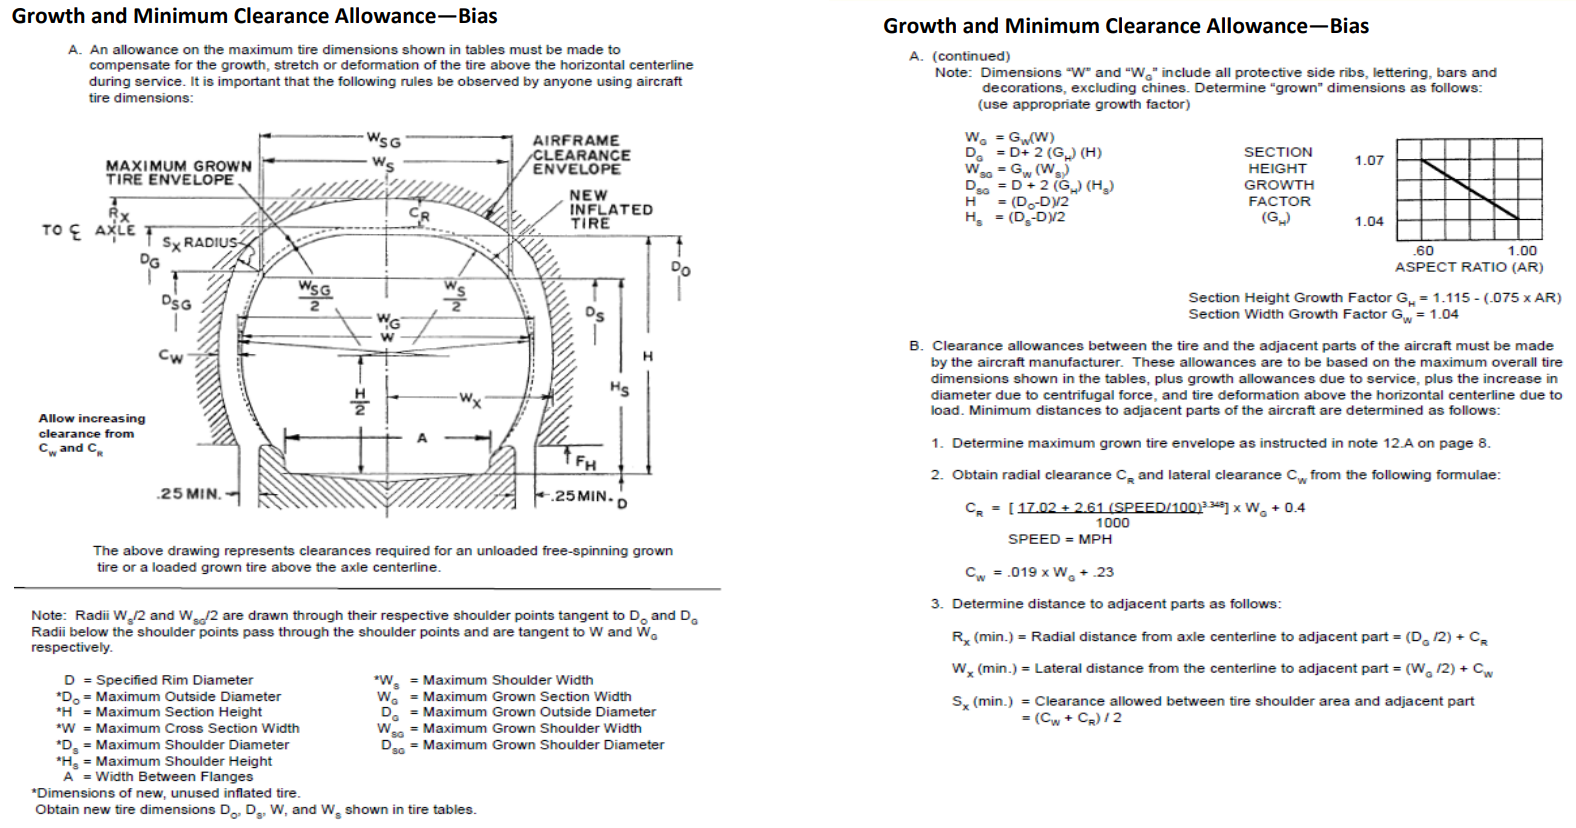

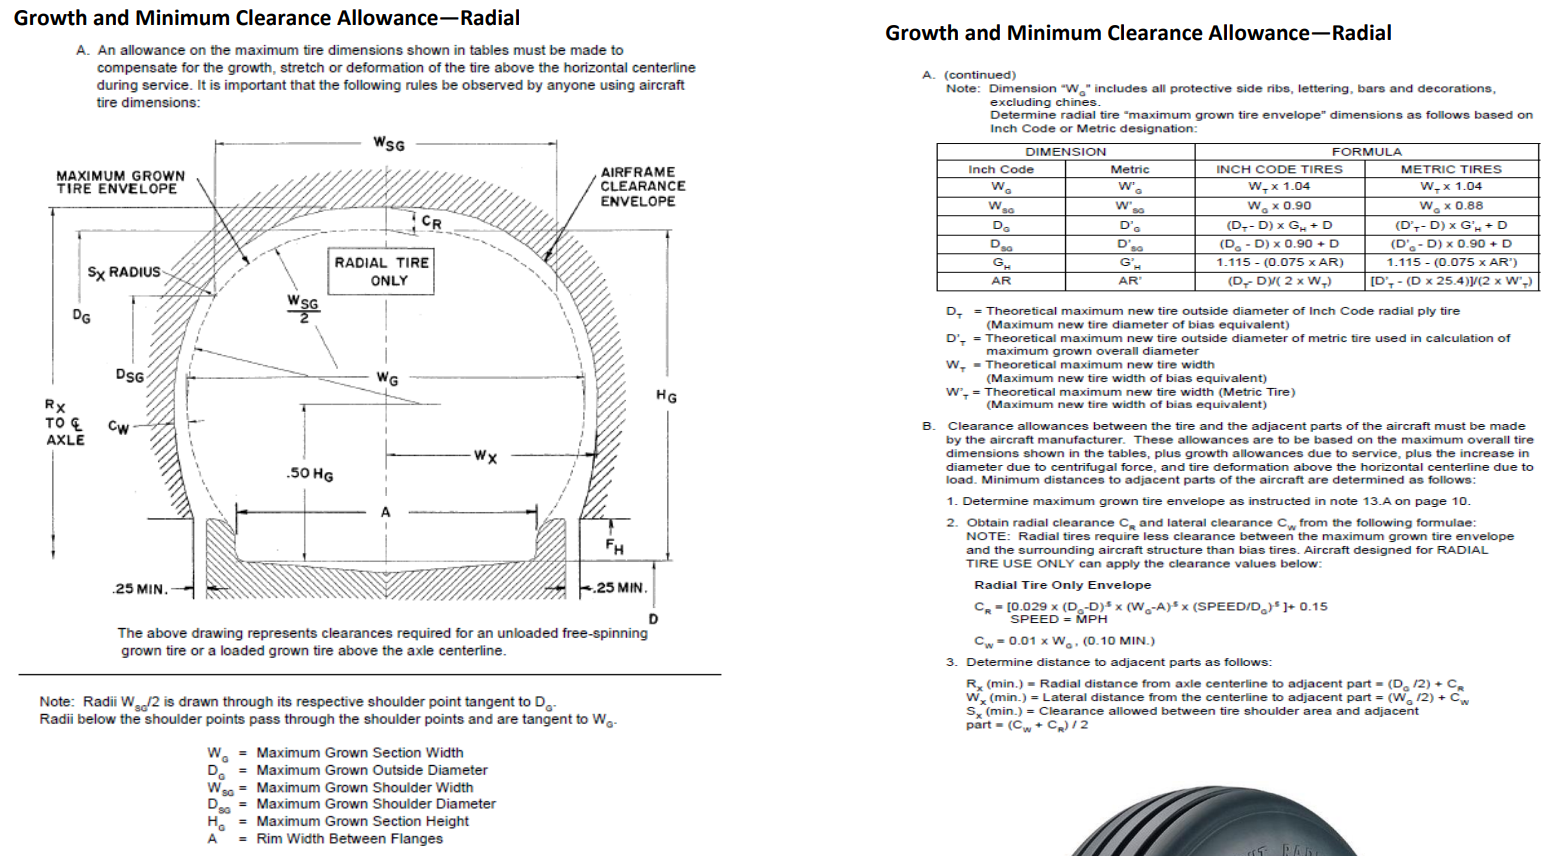

## 

## Comparison Plots

## Radial Tire Plots

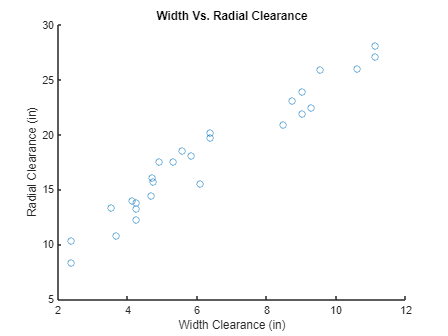



% Wg=Wt*1.04;
% Wsg=Wg*0.90;
% Dg=(Dt-D)*Gh+D;
% Dsg=(Dg-Dg)*0.90+Dg;
% AR=(DtD)/(2*Wt);
% Gh=1.115-(0.075*AR);



%Center Sections
A=ClassRadial.WidthBetweenFlanges;
D=ClassRadial.SpecifiedRimDiameter;


Wg=ClassRadial.GrownMaxSectionWdith;
Dg=ClassRadial.GrownMaxOutsideDiam;

Wsg=ClassRadial.WidthMaxShoulder;
Dsg=ClassRadial.DiameterMaxShoulder;

As=As+1; %Assumption that speed will always be 0
Speed=0;


%TireEnvolope

Cr=(0.029*(Dg-D).^0.5.*(Wg-A).^0.5.*(Speed./Dg)*0.5)+0.15;

Cw=0.01*Wg;
if Cw<0.1
    Cw=0.1;
end

% Radial distance from axle centerline to adjacent part
Rx=(Dg./2)+Cr;
% Lateral distance from centerline to adjacent part
Wx=(Wg./2)+Cw;
% Clearance allowed between tire shoulder area and adjacent part
Sx=(Cw+Cr)./2;

TableAdd=table(Cr,Cw,Rx,Wx,Sx);
ClassRadial=[ClassRadial TableAdd];

scatter(Wx,Rx)
xlabel("Width Clearance (in)")
ylabel("Radial Clearance (in)")
title("Width Vs. Radial Clearance")

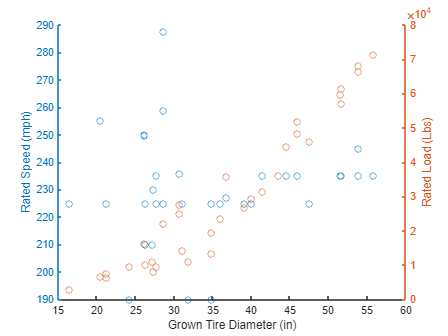



figure()
hold on
yyaxis left
scatter(ClassRadial.GrownMaxOutsideDiam,ClassRadial.RatedSpeed_MPH_)
ylabel("Rated Speed (mph)")

yyaxis right
ylabel("Rated Load (Lbs)")
scatter(ClassRadial.GrownMaxOutsideDiam,ClassRadial.RatedLoad_Lbs_)
xlabel("Grown Tire Diameter (in)")
% yline(32000,Color="red")

hold off

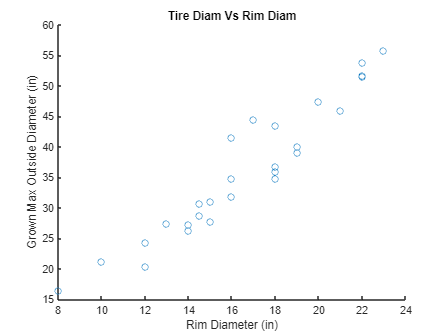

figure()
scatter(ClassRadial.SpecifiedRimDiameter,ClassRadial.GrownMaxOutsideDiam)
xlabel("Rim Diameter (in)")
ylabel("Grown Max Outside Diameter (in)")
title("Tire Diam Vs Rim Diam")

## **Overture Tire Filter Down**

The main wheel tire requirements should be based upon the most aft center of gravity location and the ground operational load-speed-time history considered to be the most severe during normal service operations.  Consideration should be given to operations at high density altitudes.

ClassRadialFiltered=ClassRadial;
disp("Tires in Radial Catalog:")

Tires in Radial Catalog:


size(ClassRadialFiltered,1)

ans = 43


%%% Filter Speed
As=As+1; %Max Tire speed
MainTireVmaxkt=190; %knot
MainTireVmax=MainTireVmaxkt*1.15078; %mph
Index=find(ClassRadialFiltered.RatedSpeed_MPH_ < MainTireVmax);
ClassRadialFiltered(Index,:) = [];
disp("Meet Max Speed Remaining:")

Meet Max Speed Remaining:


size(ClassRadialFiltered,1)

ans = 38

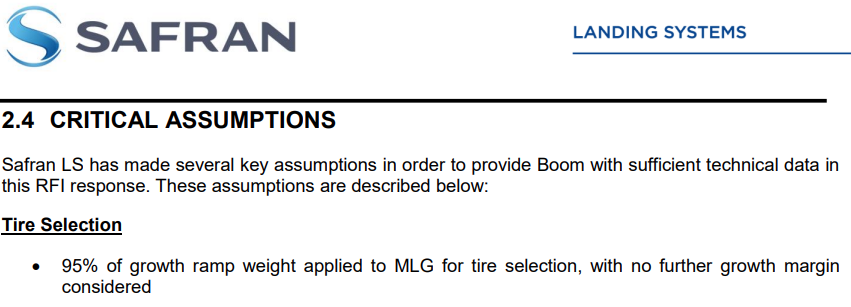

    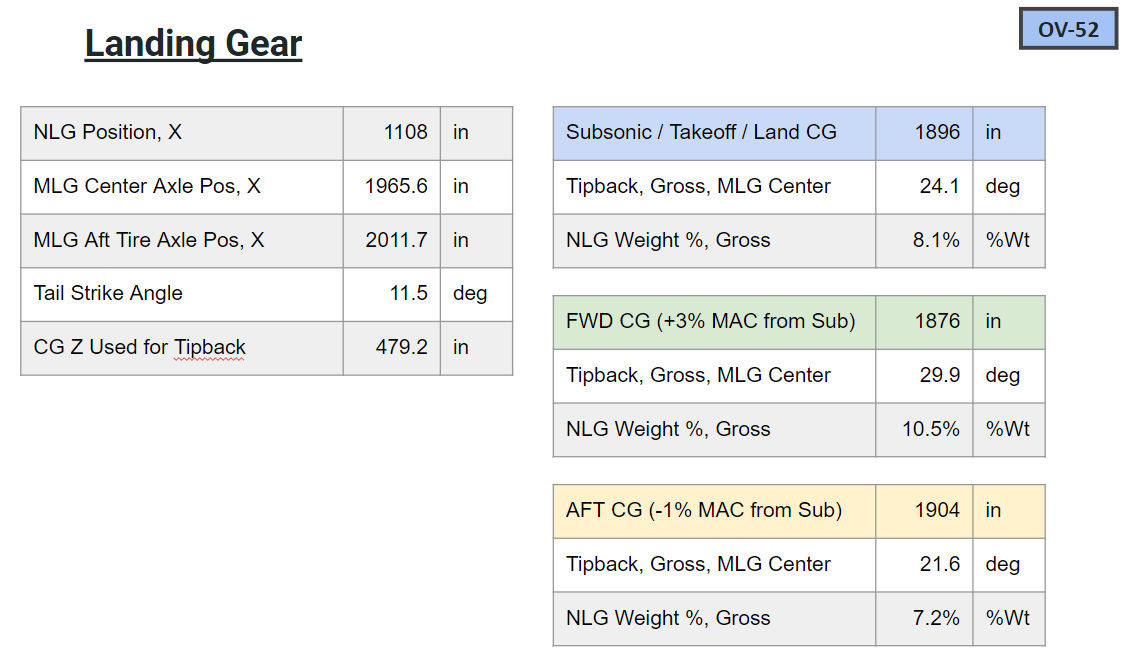

%%% Filter Load
As=As+1;
%for loads, tag up with Doug again. Taxi loads? TO loads? Taxi bump?

NLGx=1108;
MLGx=1965.6;

%FWD CG loading on nose gear
NLG_PercentLoad=((MLGx-NLGx)-(1876-NLGx))/(MLGx-NLGx);
fprintf("FWD CG loading on nose gear is %3.0f%%",NLG_PercentLoad*100)

FWD CG loading on nose gear is  10%


%AFT CG loading on main gear
MLG_PercentLoad=1-((MLGx-NLGx)-(1904-NLGx))/(MLGx-NLGx);
fprintf("AFT CG loading on main gear is %3.0f%%",MLG_PercentLoad*100)

AFT CG loading on main gear is  93%


Ove52MGW=415000;
As=As+1; %find this factor
RegulatoryFactor=1.07;









%Filter MLG Loads
%Max weight with AFT most CG
As=As+1; %Percent on main gear

MainTireFmax=Ove52MGW*RegulatoryFactor*(MLG_PercentLoad)/12;
ClassRadialFilteredMLG=ClassRadialFiltered;
Index=find(ClassRadialFilteredMLG.RatedLoad_Lbs_ < MainTireFmax);
ClassRadialFilteredMLG(Index,:) = [];
disp("Load+Speed Main Tire Options Remaining:")

Load+Speed Main Tire Options Remaining:


size(ClassRadialFilteredMLG,1)

ans = 16

disp(ClassRadialFilteredMLG.Size)

    {'36x11.0R18'                  }
    {'39x13.0R19 (Doug Gear Sheet)'}
    {'42x17.0R18'                  }
    {'43x17.5R17'                  }
    {'H44.5x16.5R21'               }
    {'H44.5x16.5R21'               }
    {'46x17.0R20'                  }
    {'46x17.0R20'                  }
    {'50x20.0R22'                  }
    {'50x20.0R22'                  }
    {'52x21.0R22'                  }
    {'52x21.0R22'                  }
    {'52x21.0R22'                  }
    {'54x21.0R23'                  }
    {'1270x455R22'                 }
    {0×0 char                      }




%Filter NLG Loads
%Max weight with FWD most CG
As=As+1; %Percent on Nose gear, hitting brakes?
MaxPercNLG=0.15;
NoseTireFmax=Ove52MGW*RegulatoryFactor*(NLG_PercentLoad)/2;
ClassRadialFilteredNLG=ClassRadialFiltered;
Index=find(ClassRadialFilteredNLG.RatedLoad_Lbs_ < NoseTireFmax);
ClassRadialFilteredNLG(Index,:) = [];
disp("Load+Speed Nose Tire Options Remaining:")

Load+Speed Nose Tire Options Remaining:


size(ClassRadialFilteredNLG,1)

ans = 22

disp(ClassRadialFilteredNLG.Size)

    {'30x11.50R14.5'               }
    {'30x11.50R14.5'               }
    {'H35x11.0R18'                 }
    {'36x11.0R18'                  }
    {'H37.5x12.0R19'               }
    {'39x13.0R19 (Doug Gear Sheet)'}
    {'H39x12.0R19'                 }
    {'40x16.0R16'                  }
    {'42x17.0R18'                  }
    {'43x17.5R17'                  }
    {'H44.5x16.5R21'               }
    {'H44.5x16.5R21'               }
    {'46x17.0R20'                  }
    {'46x17.0R20'                  }
    {'50x20.0R22'                  }
    {'50x20.0R22'                  }
    {'52x21.0R22'                  }
    {'52x21.0R22'                  }
    {'52x21.0R22'                  }
    {'54x21.0R23'                  }
    {'1270x455R22'                 }
    {0×0 char                      }



## **Tire Selection**

**Choose a MLG Tire**

filtered=true;
if filtered==true
    TireRm=string(ClassRadialFilteredMLG.Size);
else
    TireRm=string(ClassRadial.Size);    
end
MLGselection=TireRm(7);
Index=find(strcmp(TireRm,MLGselection));
if length(Index)>1
    fprintf("%1.0f variations for "+MLGselection,length(Index))
end

2 variations for 46x17.0R20


fprintf("Rated Speed:%1.1f MPH\n",ClassRadial.RatedSpeed_MPH_(Index))

Rated Speed:250.0 MPH
Rated Speed:210.0 MPH


fprintf("Rated Load:%4.2fLbs\n",ClassRadial.RatedLoad_Lbs_(Index))

Rated Load:16200.00Lbs
Rated Load:10000.00Lbs


fprintf("Rated Inflation:%4.2fPSI\n",ClassRadial.RatedInflation_PSI_(Index))

Rated Inflation:310.00PSI
Rated Inflation:210.00PSI



% fprintf("Wheel Rim Diameter:%1.1f\n",ClassRadial.SpecifiedRimDiameter(Index))
fprintf("Wheel Rim Width (Second number):%s\n",string(ClassRadial.Wheel_Rim_Size(Index)))

Wheel Rim Width (Second number):25.5x8.0-14
Wheel Rim Width (Second number):26x6.6


**Choose a NLG Tire**

filtered=true;
if filtered==true
    TireRn=string(ClassRadialFilteredNLG.Size);
else
    TireRn=string(ClassRadial.Size);    
end
NLGselection=TireRn(8);
Index=find(strcmp(TireRn,NLGselection));
if length(Index)>1
    fprintf("%1.0f variations for "+NLGselection,length(Index))
end

fprintf("Rated Speed:%1.1f MPH\n",ClassRadial.RatedSpeed_MPH_(Index))

Rated Speed:210.0 MPH


fprintf("Rated Load:%4.2fLbs\n",ClassRadial.RatedLoad_Lbs_(Index))

Rated Load:10000.00Lbs


fprintf("Rated Inflation:%4.2fPSI\n",ClassRadial.RatedInflation_PSI_(Index))

Rated Inflation:210.00PSI



% fprintf("Wheel Rim Diameter:%1.1f\n",ClassRadial.SpecifiedRimDiameter(Index))
fprintf("Wheel Rim Width (Second number):%s\n",string(ClassRadial.Wheel_Rim_Size(Index)))

Wheel Rim Width (Second number):26x6.6


**Choose a tire for comparison (Does not affect ACN numbers below)**

TireR=string(ClassRadial.Size);
Compselection=TireR(26);

Index=find(strcmp(TireR,Compselection));
if length(Index)>1
    fprintf("%1.0f variations for "+Compselection,length(Index))
end
fprintf("Rated Speed:%1.1f MPH\n",ClassRadial.RatedSpeed_MPH_(Index))

Rated Speed:225.0 MPH


fprintf("Rated Load:%4.2fLbs\n",ClassRadial.RatedLoad_Lbs_(Index))

Rated Load:26750.00Lbs


fprintf("Rated Inflation:%4.2fPSI\n",ClassRadial.RatedInflation_PSI_(Index))

Rated Inflation:212.00PSI



fprintf("Wheel Rim Diameter:%1.1f\n",ClassRadial.SpecifiedRimDiameter(Index))

Wheel Rim Diameter:19.0


**Full clearance envelope**

fprintf("Based on tire speed of %4.0f RPM", Speed)

Based on tire speed of    0 RPM

fprintf("Cr: %4.2fin\n",ClassRadial.Cr(Index))

Cr: 0.15in


fprintf("Cw: %4.2fin\n",ClassRadial.Cw(Index))

Cw: 0.12in


fprintf("Sx: %4.2fin\n",ClassRadial.Sx(Index))

Sx: 0.14in


## ACN Analysis

AC 150/5335-5D - Standardized Method of Reporting Airport Pavement Strength - PCR

[https://www.faa.gov/airports/resources/advisory_circulars/index.cfm/go/document.current/documentnumber/150_5335-5](https://www.faa.gov/airports/resources/advisory_circulars/index.cfm/go/document.current/documentnumber/150_5335-5)

Starting in the year 2020 and to be fully in force by the year 2024, the ACR/PCR system will replace the ACN/PCN methodology, by agreement of the ICAO.

SLS RFI page 14

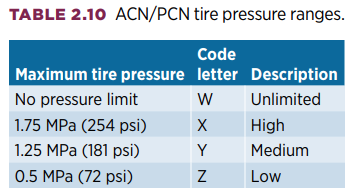

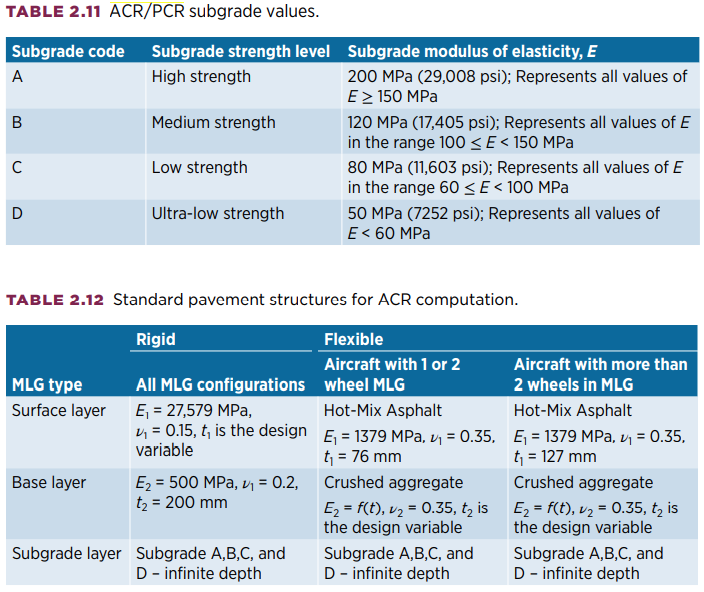

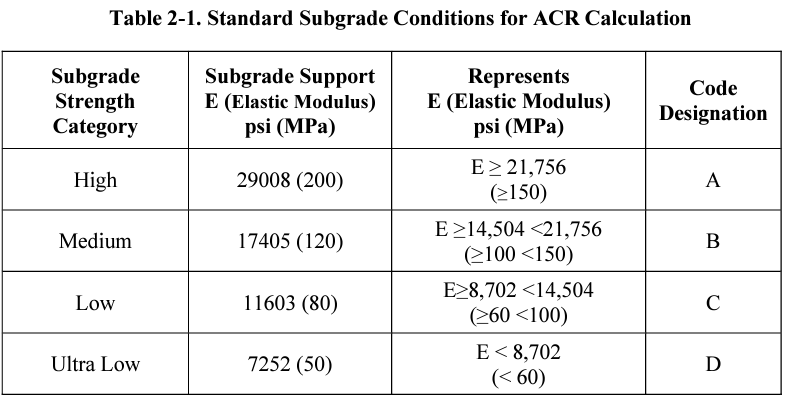    

## **Notes**

fprintf("Questionable Assumptions:%4.0f",Q)
fprintf("Qestions:%4.0f",As)
Questions=Q;
Assumptions=As;




Questionable Assumptions:   0

Qestions:   6